# Configurations of the operational amplifiers

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

## Introduction

This notebook provides an introduction to operational amplifiers and models for a:

- The model of an operational amplifier

- Basic amplifier configurations

## Operational amplifier

Operational amplifiers are characterized using several parameters such as:

- Open-loop gain where $V_0 =A\left(V_1 -V_2 \right)$ and can be order of million

- Input resistance, $R_{\textrm{in}}$ that should be very high, for example in the order of GΩ

- Output resistance, $R_{\textrm{out}}$ that is commonly low in order of 100 Ω

- Minimum and maximum output voltage

- Maximum slew rate which is the maximum positive or negative rate of change of output voltage magnitude. A typical number is, for example, 2.8 V/µs.

- Open-loop bandwidth is the frequency at which the gain drops by 3 dB in comparison with the gain at low frequencies. 

Operational amplifiers are normally used in negative feedback configuration in which the output is connected to one input. By doing that, the ideal operational amplifier will adjust the output until the difference of the voltages at input is close to zero. 

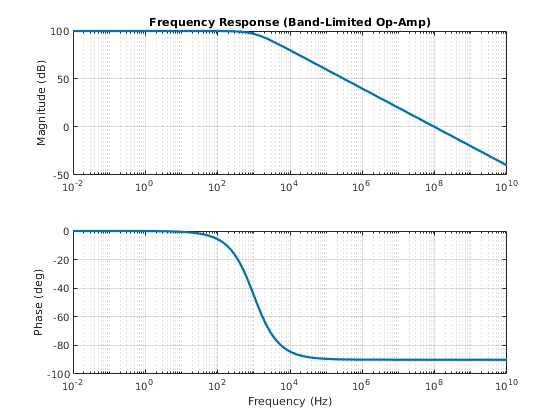

 % Please note that we are using the model provided by Mathworks here.

% Run linearization 
figure
%% Open the model and set circuit parameters
open_system('ssc_opamp_bandlimited')
%% Linearize
[a,b,c,d]=linmod('ssc_opamp_bandlimited');
ssc_opamp_bandlimited_bodeplot

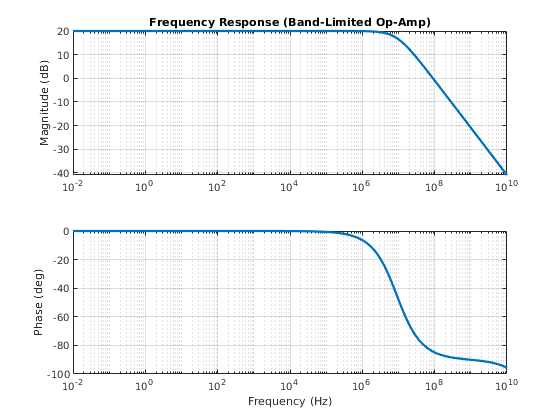

figure
%% Open the model and set circuit parameters
open_system('ssc_opamp_bandlimited_noninverting')

%% Linearize
[a,b,c,d]=linmod('ssc_opamp_bandlimited_noninverting');
ssc_opamp_bandlimited_bodeplot

## Exersizes

Excersize 1: Analyze frequency response of the op-amp model without the feedback circuit. What is the Gain BandWidth Product (GBWP)? 

Excersize 2: Analyze frequency response of the op-amp model acting as an invertiong amplifier. What is the Gain BandWidth Product (GBWP)? 

## Inverting amplifier

model_name = 'inverting';
open_system(model_name);

ScopeData1=sim(model_name);

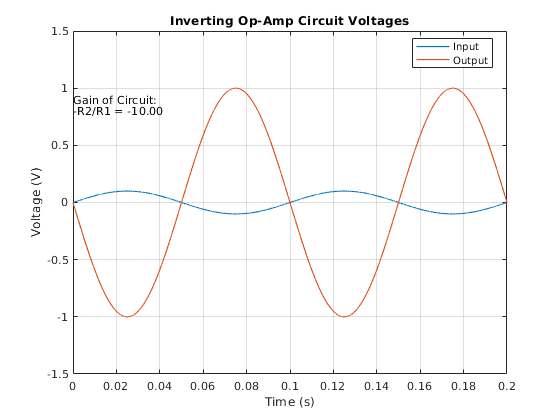

temp_vin = simlog_ssc_opamp_inverting.AC_Voltage.v.series;
temp_vout = simlog_ssc_opamp_inverting.Sensor_Vout.Voltage_Sensor.V.series;

% Plot results
figure
plot(temp_vin.time,temp_vin.values,'LineWidth',1);
hold on
plot(temp_vout.time,temp_vout.values,'LineWidth',1);
hold off
text(0.1e-3,0.9,'Gain of Circuit:');
text(0.1e-3,0.8,sprintf('%s %2.2f','-R2/R1 =',-max(temp_vout.values)/max(temp_vin.values)));
grid on
title('Inverting Op-Amp Circuit Voltages');
ylabel('Voltage (V)');
xlabel('Time (s)');
ylim([-1.5,1.5])
legend({'Input','Output'},'Location','Best');

## Noninverting amplifier

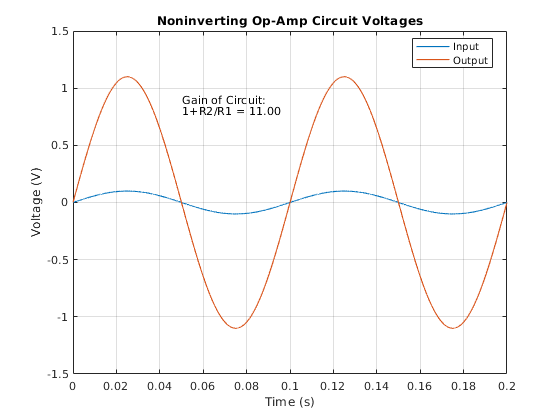

clear all
model_name = 'noninverting1';
open_system(model_name);
sim(model_name);
temp_vin = simlog_ssc_opamp_noninverting.Sensor_Vin.Voltage_Sensor.V.series;
temp_vout = simlog_ssc_opamp_noninverting.Sensor_Vout.Voltage_Sensor.V.series;

% Plot results
figure
plot(temp_vin.time,temp_vin.values,'LineWidth',1);
hold on
plot(temp_vout.time,temp_vout.values,'LineWidth',1);
hold off
text(0.05,0.9,'Gain of Circuit:');
text(0.05,0.8,sprintf('%s %2.2f','1+R2/R1 =',max(temp_vout.values)/max(temp_vin.values)));
grid on
title('Noninverting Op-Amp Circuit Voltages');
ylabel('Voltage (V)');
xlabel('Time (s)');
ylim([-1.5,1.5])
legend({'Input','Output'},'Location','Best');

## Differentiator

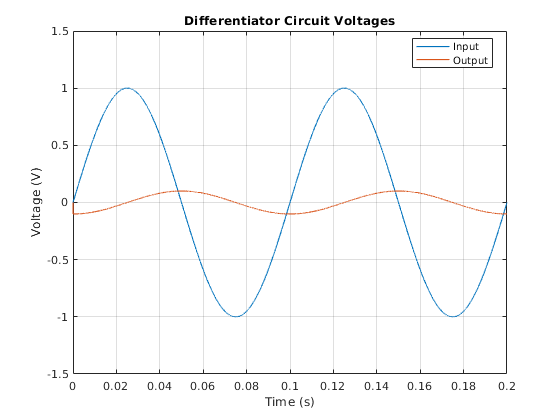

clear all
model_name = 'differentiator';
open_system(model_name);
sim(model_name);
% Get simulation results
temp_vin = simout.Data(:,2);
temp_vout = simout.Data(:,1);

% Plot results
figure
plot(simout.Time,temp_vin,'LineWidth',1);
hold on
plot(simout.Time,temp_vout,'LineWidth',1);
hold off
grid on
title('Differentiator Circuit Voltages');
ylabel('Voltage (V)');
xlabel('Time (s)');
ylim([-1.5,1.5])
legend({'Input','Output'},'Location','Best');

## Integrator

This is the integrator from the Problem 4.17 from the book. Please note that the values of the resistance and the capacitance are not set properly and that this should be done in order to solve Problem 4.17.

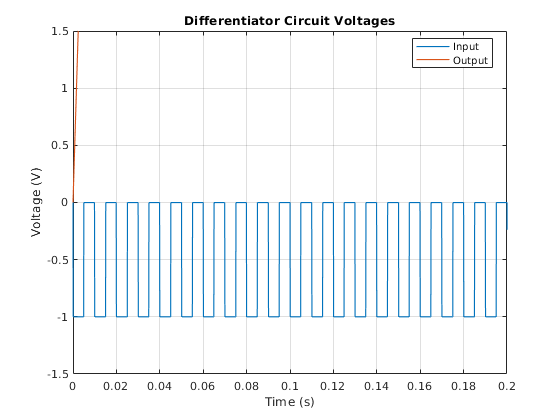

clear all
model_name = 'integrator1';
open_system(model_name);
T=0.0001;

t=0:T:2;
a=sin(2*pi*t*100);
ind=find(a>0);
pulse1=zeros(1, length(a));
pulse1(ind)=-1;
Vin(:,1)=t; %time;
Vin(:,2)=pulse1;

sim(model_name);
% Get simulation results
temp_vin = simout.Data(:,2);
temp_vout = simout.Data(:,1);

% Plot results
figure
plot(simout.Time,temp_vin,'LineWidth',1);
hold on
plot(simout.Time,temp_vout,'LineWidth',1);
hold off
grid on
title('Differentiator Circuit Voltages');
ylabel('Voltage (V)');
xlabel('Time (s)');
ylim([-1.5,1.5])
xlim([0,0.2])
legend({'Input','Output'},'Location','Best');